# Laboratorio di Automatica (Prova del 23 Giugno 2020)

Riccardo Antonello ([antonello@dei.unipd.it](mail:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mail:schenato@dei.unipd.it)) 

June 23, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 3

In Fig. 3 è riportato lo schema di controllo di velocità di un motore elettrico in corrente continua che fa uso di un *disturbance observer (DOB)*. Il motore ha funzione di trasferimento:


$$P(s)\,=\, \frac{\Theta(s)}{U_2(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


da ingresso in tensione $u$ $[V]$ ad uscita in posizione $\vartheta$ $[\mathrm{rad}]$. Il controllore di velocità $C(z)$ è la versione discretizzata, con il metodo di *Eulero in Indietro* (*Backward Euler*), del seguente controllore PD (con derivata reale) a tempo continuo:


$$C(s) =\frac{U_C(s)}{E(s)} = K_P \,+\, \frac{K_D\,s }{T_L\,s + 1}
\quad\text{con}\quad
K_P = 0.472\,,\quad
K_D=0.016\,,\quad
T_L=0.004$$


con ingresso l'errore di velocità $e\,\mathrm{[rad/s]}$ ed uscita la tensione di comando $u_C\,[\mathrm{V}]$. Il compensatore in feedforward è un guadagno statico del tipo:


$$F(z) = \frac{U_F(z)}{\Omega^*(z)}=\frac{1}{k_m}$$


Il blocco con funzione di trasferimento $H(z)$ è un filtro "derivatore reale" utilizzato per ricavare una stima $\omega\,\mathrm{[rad/s]$ della velocità del motore a partire dalla misura di posizione $\vartheta\,[\mathrm{rad}]$; è ottenuto discretizzando, *con il metodo di Eulero all'Indietro (Backward Euler)*, il seguente filtro a tempo continuo:


$$H(s) = \frac{\Omega(s)}{\Theta(s)} = \frac{\omega_c^2\,s}{s^2 + 2 \delta \omega_c s + \omega_c^2}
\quad\text{con}\quad
\omega_c = 2 \pi\,5\,\mathrm{rad/s},\,\quad
\delta=\frac{1}{\sqrt{2}}$$


Nel DOB, $P_n(z)$ rappresenta la versione discretizzata, *con il metodo esatto*, della funzione di trasferimento nominale a tempo continuo $P_n(s)$ dell'impianto da controllare, che nel seguito verrà assunta pari a $P(s)$. Invece, $Q(z)$ è la versione discretizzata, con il *metodo di Eulero in Avanti (Forward Euler)*, del seguente filtro passa-basso a tempo continuo:


$$Q(s) \,=\, \frac{\omega_n^2}{s^2 + 2\delta\omega_n s + \omega_n^2}\qquad\text{con}\qquad \omega_n = 2\pi\,10\,\mathrm{rad/s}\,,\quad \delta = \frac{1}{\sqrt{2}}$$


necessario per la fisica realizzabilità del DOB, e per la reiezione del rumore di misura.

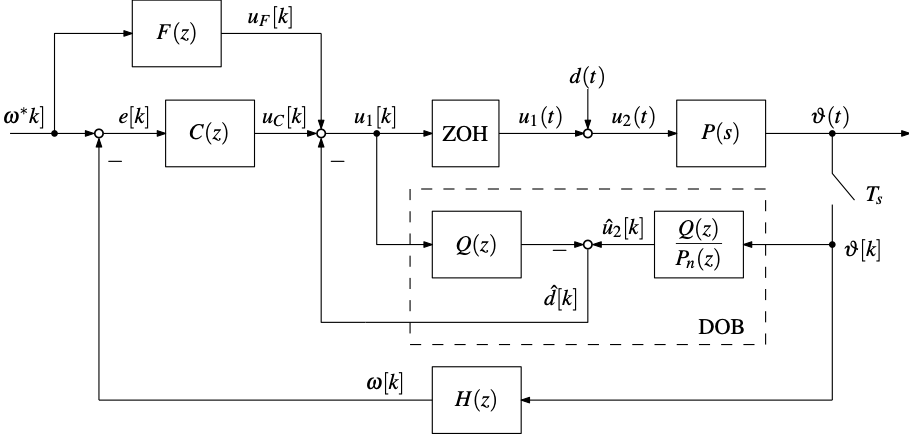

**Figura 3**: Sistema di controllo di velocità a tempo discreto con DOB.

Considerando un tempo di campionamento $T_s = 0.01\,\mathrm{s}$, si svolgano i seguenti punti: 

1) Realizzare uno schema Simulink del sistema di controllo di Fig. 3. Si assuma che:

- la tensione $u_1(t)$ sia fornita da un DAC (digital-to-analog converter) a 10 bit e range d uscita pari a $\pm\,10\,V$.

- la misura di posizione $\vartheta[k]$ sia fornita da un encoder con risoluzione pari a $2000\,\mathrm{ppr}$ (*pulses-per-rotation*, ovvero impulsi-per-giro).

Nota: per simulare sia il campionatore che lo Zero-Order Holder (ZOH), si faccia ricorso al blocco `Discrete `$\rightarrow$` Zero-Order Hold` della libreria di blocchi del Simulink.

*Soluzione*.

%   conversion gains
rads2rpm = 60/2/pi;
rpm2rads = 2*pi/60;

%   sampling time
Ts = 10e-3;

%   motor tf
km = 5.2;
Tm = 0.03;
numP = km;
denP = [Tm, 1, 0];

%   speed filter tf
z = tf('z', Ts);
s = (z-1)/Ts/z;

wc = 2*pi*5;
d = 1/sqrt(2);
sysH = minreal( wc^2*s/(s^2 + 2*d*wc*s + wc^2) );
[numH, denH] = tfdata(sysH, 'v');

%   PD controller tf
Kp = 0.472;
Kd = 0.016;
TL = 0.004;

sysC = minreal( Kp + Kd*s/(TL*s + 1) );
[numC, denC] = tfdata(sysC, 'v');

%   DOB tfs - low-pass filter Q(z)
wn = 2*pi*10;
s = (z-1)/Ts;
sysQ = wn^2/(s^2 + 2*d*wn*s + wn^2);
[numQ, denQ] = tfdata(sysQ, 'v');

%   DOB tfs - nominal plant Pn(z)
sysPn = tf(numP, denP);
sysPn = c2d(sysPn, Ts, 'zoh');
[numPn, denPn] = tfdata(sysPn, 'v');

%   DOB params - filter W(z)=Q(z)/Pn(z)
sysW = minreal( sysQ/sysPn );
[numW, denW] = tfdata(sysW, 'v');

%    open Simulink model
open_system('ex3_sim1')

2) Simulare la risposta del sistema di controllo con un riferimento di velocità $\omega^*$ a gradino di ampiezza $A_r= 250\,\mathrm{rpm}$ applicato in $t_r = 0\,\mathrm{s}$, e un disturbo $d$ a gradino di ampiezza $A_d = 5\,\mathrm{V}$, applicato in $t_d = 1\,\mathrm{s}$. Si imposti un tempo finale di simulazione adeguato (es. $2\,\mathrm{s}$).

*Soluzione*.

%    set reference params (amplitude & start time)
Ar = 250*rpm2rads;  t0r = 0;  

%    set disturbance params (amplitude & start time)
Ad = 5;  t0d = 1;  

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.01', 'StopTime','2');

%    run simulation
sim('ex3_sim1');

3)  Con riferimento alla simulazione eseguita al punto 2, mostrare in una figura MATLAB gli andamenti dei seguenti segnali: 	

- plot 1: velocità misurata $\omega[k]$ e riferimento $\omega^*[k]$, entrambi espressi in $[\mathrm{rpm}]$.

- plot 2: errore di inseguimento $e[k]$, espresso in $[\mathrm{rpm}]$.

- plot 3: comando di tensione $u_1(t)$ in $[V]$.

- plot 4: disturbo $d(t)$ e stima del disturbo $\hat{d}[k]$, entrambi espressi in $[\mathrm{V}]$.

Verificare che grazie alla presenza del DOB, il sistema di controllo è in grado di reiettare completamente il disturbo di carico costante, anche in assenza dell'azione integrale nel controllore.	

*Soluzione*.

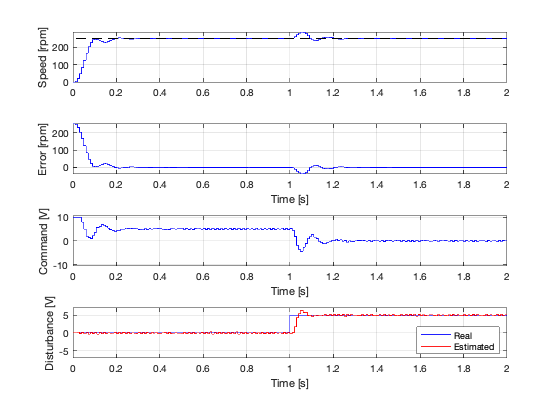

%   extract signas
t = simres.time;
w_meas = simres.signals(1).values(:,1);
w_ref = simres.signals(1).values(:,2);
e = simres.signals(2).values;
u1 = simres.signals(3).values;
d = simres.signals(4).values;
d_est = simres.signals(5).values;

%   plot results
figure;
subplot(4,1,1);
stairs(t, w_meas, 'b');
hold on;
stairs(t, w_ref, 'k--');
grid on;
ylabel('Speed [rpm]');

subplot(4,1,2);
stairs(t, e, 'b');
grid on;
ylabel('Error [rpm]');
xlabel('Time [s]');

subplot(4,1,3);
stairs(t, u1, 'b');
grid on;
ylim([-10.5, 10.5]);
ylabel('Command [V]');
xlabel('Time [s]');

subplot(4,1,4);
plot(t, d, 'b');
hold on;
stairs(t, d_est, 'r');
grid on;
ylabel('Disturbance [V]');
xlabel('Time [s]');
ylim([-7, 7]);
hl = legend('Real', 'Estimated');
set(hl, 'Location', 'SouthEast');